%%%%%%%%%%%%%%%%%%%%%%
%%%graphical abstract plots
%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

%%canister data, including data with all flags
%SDK
ppbSDK = readtimetable("ppb SDK.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSDKnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSDKnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKATEC = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ppbSDKATECnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC no LK", "VariableNamingRule", "preserve");
ppbSDKATECnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKEnt = readtimetable("ppb SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ppbSDKEntnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "Ent no LK", "VariableNamingRule", "preserve");
ppbSDKEntnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "Ent no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKPicarro = readtimetable("ppb SDK.xlsx", "Sheet", "Picarro", "VariableNamingRule", "preserve");

%STER
ppbSTER = readtimetable("ppb STER.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSTERnoLK = readtimetable("ppb STER.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSTERnoHg = readtimetable("ppb STER.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%SSG
ppbSSG = readtimetable("ppb SSG.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSSGnoLK = readtimetable("ppb SSG.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSSGnoHg = readtimetable("ppb SSG.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%COV
ppbCOV = readtimetable("ppb COV.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbCOVnoLK = readtimetable("ppb COV.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbCOVnoHg = readtimetable("ppb COV.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
cd ..

%SDK, AROMA
ppbAROMA = readtimetable("etoAROMA_SDK.xlsx");

cd ../.. %return to data folder

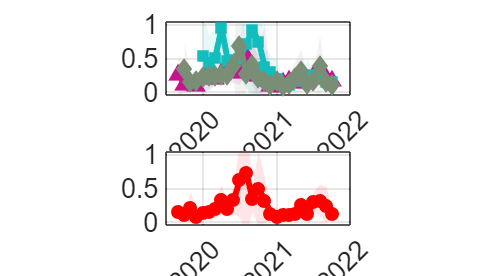

%%%%%%%%%%%%%%%%%%%%%%
%%%PLOT FIGURE TIMESERIES WITH NEAR-SOURCE and BACKGROUND TO-15 PASSIVE
%%%SEPARATE
%%%%%%%%%%%%%%%%%%%%%%

fig = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(2, 1, "TileSpacing", "compact")

%%%a. Time Series
%%%INPUTS
dataSDKEnt = ppbSDKEnt;
dataSDKATEC = ppbSDKATEC;
dataSDKPicarro = ppbSDKPicarro;
dataSTER = ppbSTER;
dataSSG = ppbSSG;
dataCOV = ppbCOV;
colorSTER = [0.769, 0.080, 0.557];
colorSSG = [0.071, 0.74, 0.74];
colorCOV = [122, 142, 117]/255;
colorAROMA = [0.8392, 0.5686, 0.3098];
controlsSTER = datetime(2020, 4, 8);
controlsSSG = datetime(2021, 1, 26);
controlsCOV = datetime(2020, 3, 31);
colors = [1, 0, 0; 0, 0, 1; 0, 0, 0; colorAROMA; colorSTER; colorSSG; colorCOV];
xlims = datetime([2019, 2022], [7, 1], 1);
xtickss = (xlims(1)+calmonths(6)):calmonths(12):datetime(2022, 7, 1);
ylims = [-0.05, 1.05];
ytickss = 0:0.5:1;

%%plot near-source
ax = nexttile;
hold on
grid on
box on

hl = gobjects(3, 1);

%STER
dataMonthSTER = binByMonth(dataSTER); %upwind STER, bin by month
times = datenum(dataMonthSTER.Properties.RowTimes); %grab date nums
[hl(1), hp] = boundedline(times, dataMonthSTER.avgs, dataMonthSTER.stds, ...
    '^-', 'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colorSTER);
hl(1).MarkerSize = 6; %change line aspects
hl(1).MarkerFaceColor = colorSTER;
hl(1).LineWidth = 4.5;

%SSG
dataMonthSSG = binByMonth(dataSSG); %upwind SSG, bin by month
times = datenum(dataMonthSSG.Properties.RowTimes); %grab date nums
[hl(2), hp] = boundedline(times, dataMonthSSG.avgs, dataMonthSSG.stds, ...
    'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colorSSG);
hl(2).Marker = "square";
hl(2).MarkerSize = 7; %change line aspects
hl(2).MarkerFaceColor = colorSSG;
hl(2).LineWidth = 4.5;

%COV
dataMonthCOV = binByMonth(dataCOV); %upwind COV, bin by month
times = datenum(dataMonthCOV.Properties.RowTimes); %grab date nums
[hl(3), hp] = boundedline(times, dataMonthCOV.avgs, dataMonthCOV.stds, ...
    'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colorCOV);
hl(3).Marker = "diamond";
hl(3).MarkerSize = 7; %change line aspects
hl(3).MarkerFaceColor = colorCOV;
hl(3).LineWidth = 4.5;

%move lines to top
uistack(hl(1), 'top')
uistack(hl(2), 'top')
uistack(hl(3), 'top')

%%lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "yyyy");
ylim(ylims)
yticks(ytickss)

%%labels
pbaspect([2.5, 1, 1])
ax.FontSize = 20;
% xlabel("Local Time (EST)")
% ylabel("EtO (ppb)")

hold off

%%plot background
ax = nexttile;
hold on
grid on
box on

hl = gobjects(1, 1);

%SDK, passive
dataMonthSDKEnt = binByMonth(dataSDKEnt); %upwind STER, bin by month
times = datenum(dataMonthSDKEnt.Properties.RowTimes); %grab date nums
[hl(1), hp] = boundedline(times, dataMonthSDKEnt.avgs, dataMonthSDKEnt.stds, ...
    'o-', 'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colors(1, :));
hl(1).MarkerSize = 6; %change line aspects
hl(1).MarkerFaceColor = colors(1, :);
hl(1).LineWidth = 4.5;

%move lines to top
uistack(hl(1), 'top')

%%lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "yyyy");
ylim(ylims)
yticks(ytickss)

%%labels
pbaspect([2.5, 1, 1])
ax.FontSize = 20;
% xlabel("Local Time (EST)")
% ylabel("EtO (ppb)")

hold off

% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Figure GraphAbstract Timeseries.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again

% cd ..\Data

%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

%%canister data, including data with all flags
%SDK
ARSDK = readtimetable("AR SDK.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSDKnoLK = readtimetable("AR SDK.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSDKnoHg = readtimetable("AR SDK.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
ARSDKATEC = readtimetable("AR SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ARSDKATECnoLK = readtimetable("AR SDK.xlsx", "Sheet", "ATEC no LK", "VariableNamingRule", "preserve");
ARSDKATECnoHg = readtimetable("AR SDK.xlsx", "Sheet", "ATEC no 0 Hg", "VariableNamingRule", "preserve");
ARSDKEnt = readtimetable("AR SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ARSDKEntnoLK = readtimetable("AR SDK.xlsx", "Sheet", "Ent no LK", "VariableNamingRule", "preserve");
ARSDKEntnoHg = readtimetable("AR SDK.xlsx", "Sheet", "Ent no 0 Hg", "VariableNamingRule", "preserve");

%STER
ARSTER = readtimetable("AR STER.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSTERnoLK = readtimetable("AR STER.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSTERnoHg = readtimetable("AR STER.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%SSG
ARSSG = readtimetable("AR SSG.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSSGnoLK = readtimetable("AR SSG.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSSGnoHg = readtimetable("AR SSG.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%COV
ARCOV = readtimetable("AR COV.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARCOVnoLK = readtimetable("AR COV.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARCOVnoHg = readtimetable("AR COV.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

cd ../../..

%%%%%%%%%%%%%%%%%%%%%%
%%% subtraction of AR for comparison histograms
%%%%%%%%%%%%%%%%%%%%%%

%%INPUTS
dataSDK = ARSDKEnt(:, ["Ent_ERG", "Ent_ERG_2"]); %passive SDK at ERG ONLY
dataSTER = ARSTER; %STER
dataSSG = ARSSG; %SSG
dataCOV = ARCOV; %COV

%%grab inds or days with coupled observations
%all data
outTTSTER = avSameTime(dataSDK, dataSTER); %[SDKavg, SDKstd, STERavg, STERstd]
outTTSSG = avSameTime(dataSDK, dataSSG); %[SDKavg, SDKstd, SSGavg, SSGstd]
outTTCOV = avSameTime(dataSDK, dataCOV); %[SDKavg, SDKstd, COVavg, COVstd]

%%subtraction of each individual near-source site by SDK, separated also by upwind, downwind, and all
%STER
inds = ismember(dataSTER.time, outTTSTER.time); %times SDK and STER match
temp = timetable2array(dataSTER(inds, :)); %grab all STER data
temp = temp - repmat(outTTSTER.avg1, 1, size(temp, 2));
diffSTER = array2timetable(temp, "RowTimes", outTTSTER.time, ...
    "VariableNames", dataSTER.Properties.VariableNames); %STER, all data

%SSG
inds = ismember(dataSSG.time, outTTSSG.time); %times SDK and SSG match
temp = timetable2array(dataSSG(inds, :)); %grab all SSG data
temp = temp - repmat(outTTSSG.avg1, 1, size(temp, 2));
diffSSG = array2timetable(temp, "RowTimes", outTTSSG.time, ...
    "VariableNames", dataSSG.Properties.VariableNames); %SSG

%COV
inds = ismember(dataCOV.time, outTTCOV.time); %times SDK and COV match
temp = timetable2array(dataCOV(inds, :)); %grab all COV data
temp = temp - repmat(outTTCOV.avg1, 1, size(temp, 2));
diffCOV = array2timetable(temp, "RowTimes", outTTCOV.time, ...
    "VariableNames", dataCOV.Properties.VariableNames); %COV

%%%%%%%%%%%%%%%%%%%%%%
%%% FIGURE 5
%%%%%%%%%%%%%%%%%%%%%%

colorUpwind = [73, 191, 162]/255;
colorDownwind = [226, 84, 175]/255;
controlsSTER = datetime(2020, 4, 8);
controlsSSG = datetime(2021, 1, 26);
controlsCOV = datetime(2020, 3, 31);
patchColor = [0.7, 0.7, 0.7];

%%% STER
fig = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 3)

%%1. histograms STER
ax = nexttile;
hold on
grid on
box on

binWidths = 0.001;
beforeColor = [1, 0, 0];
afterColor = [0, 0.5, 1];

%%all data as histograms
indsBefore = diffSTER.Properties.RowTimes < controlsSTER; %before controls
h1 = histogram(unravelTT(diffSTER(indsBefore, :)), "Normalization", "probability");
h1.BinWidth = binWidths;
h1.EdgeColor = "none"; %remove outer outline
h1.FaceAlpha = 0.5;
h1.FaceColor = beforeColor;
median(unravelTT(diffSTER(indsBefore, :)))

ans = 5.0000e-05


indsAfter = diffSTER.Properties.RowTimes >= controlsSTER; %after controls
h2 = histogram(unravelTT(diffSTER(indsAfter, :)), "Normalization", "probability");
h2.BinWidth = binWidths;
h2.EdgeColor = "none"; %remove outer outline
h2.FaceAlpha = 0.5;
h2.FaceColor = afterColor;
median(unravelTT(diffSTER(indsAfter, :)))

ans = -1.0000e-04


%%line at SDK uncertainties to signify comparison 
xline(0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)
xline(-0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

%%lims
xlim([-0.0208, 0.0208])
xticks(-0.020:0.01:0.020)
ylim([0, 0.4])
% yticks(0:20:80)

%%labels
pbaspect([1.3, 1, 1])
ax.FontSize = 20;
% xlabel("AR Enhancement")
% ylabel("Normalized Observation Counts")

% legend(strcat("before startup, n=", num2str(length(unravelTT(diffSTER(indsBefore, :))))), ...
%     strcat("after startup, n=", num2str(length(unravelTT(diffSTER(indsAfter, :))))), ...
%     "location", "northeast", "Fontsize", 17)

hold off



%%2. histograms, SSG
ax = nexttile;
hold on
grid on
box on

% binWidths = 0.0025;
binWidths = 0.0015;

%%all data as histograms
indsBefore = diffSSG.Properties.RowTimes < controlsSSG; %before controls
h1 = histogram(unravelTT(diffSSG(indsBefore, :)), "Normalization", "probability");
h1.BinWidth = binWidths;
h1.EdgeColor = "none"; %remove outer outline
h1.FaceAlpha = 0.5;
h1.FaceColor = beforeColor;
medSSGBefore = median(unravelTT(diffSSG(indsBefore, :)))

medSSGBefore = 0.0013


indsAfter = diffSSG.Properties.RowTimes >= controlsSSG; %after controls
h2 = histogram(unravelTT(diffSSG(indsAfter, :)), "Normalization", "probability");
h2.BinWidth = binWidths;
h2.EdgeColor = "none"; %remove outer outline
h2.FaceAlpha = 0.5;
h2.FaceColor = afterColor;
median(unravelTT(diffSSG(indsAfter, :)))

ans = 2.5000e-04


%%line at SDK uncertainties to signify comparison 
xline(0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)
xline(-0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

%%lims
xlim([-0.021, 0.031])
xticks(-0.02:0.01:0.03)
ylim([0, 0.6])
% yticks(0:15:60)

%%labels
pbaspect([1.3, 1, 1])
ax.FontSize = 20;
% xlabel("AR Enhancement")
% ylabel("Normalized Observation Counts")

% legend(strcat("before controls, n=", num2str(length(unravelTT(diffSSG(indsBefore, :))))), ...
%     strcat("after controls, n=", num2str(length(unravelTT(diffSSG(indsAfter, :))))), ...
%     "location", "northeast", "Fontsize", 17)
% legend boxoff

hold off


%%3. histograms, COV
ax = nexttile;
hold on
grid on
box on

% shutdown times not to be included
shutdownCOV = datetime([2019, 2019, 2020, 2020], ...
    [10, 11, 2, 3], ...
    [30, 8, 22, 2]); %shutdowns between Oct 30 and Nov 8, 2019 and Feb 22 and Mar 2, 2020
indsShutdown = isbetween(diffCOV.Properties.RowTimes, shutdownCOV(1), shutdownCOV(2)); %first period
indsShutdown = indsShutdown | ...
    isbetween(diffCOV.Properties.RowTimes, shutdownCOV(3), shutdownCOV(4)); %second period

% binWidths = 0.0025;
binWidths = 0.0015;

%%all data as histograms
indsBefore = diffCOV.Properties.RowTimes < controlsCOV; %before controls, exclude shutdown
h1 = histogram(unravelTT(diffCOV(indsBefore & ~indsShutdown, :)), "Normalization", "probability");
h1.BinWidth = binWidths;
h1.EdgeColor = "none"; %remove outer outline
h1.FaceAlpha = 0.5;
h1.FaceColor = beforeColor;
median(unravelTT(diffCOV(indsBefore & ~indsShutdown, :)))

ans = 6.5000e-04


indsAfter = diffCOV.Properties.RowTimes >= controlsCOV; %after controls
h2 = histogram(unravelTT(diffCOV(indsAfter, :)), "Normalization", "probability");
h2.BinWidth = binWidths;
h2.EdgeColor = "none"; %remove outer outline
h2.FaceAlpha = 0.5;
h2.FaceColor = afterColor;
median(unravelTT(diffCOV(indsAfter, :)))

ans = -5.0000e-05

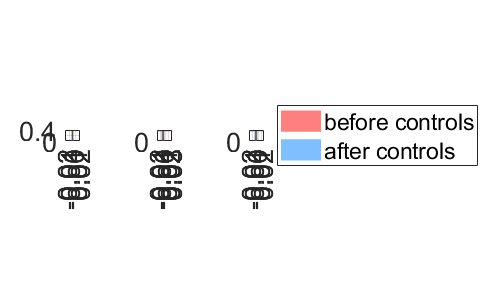


%%line at SDK uncertainties to signify comparison 
xline(0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)
xline(-0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

%%lims
xlim([-0.0209, 0.0259])
xticks(-0.020:0.01:0.020)
ylim([0, 0.6])
% yticks(0:15:60)

%%labels
pbaspect([1.3, 1, 1])
ax.FontSize = 20;
% xlabel("AR Enhancement")
% ylabel("Normalized Observation Counts")

% legend("before controls", ...
%     "after controls", ...
%     "location", "eastoutside", "Fontsize", 17)
% legend boxoff

hold off

% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Figure GraphAbstract near-source.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again

% cd ..\Data